clear all; 
% select the initial point: x0
% step size: dx
% hyperparameter: gamma
% last change 20/8/2024

x0 = 1.28; dx = 1e-2; gamma = 1.2; 

f = @(x) x.^2 + 54./x;


[a, c] = bracket_minimum(f,x0, dx, gamma)

a = 1.9100

c = 3.8300

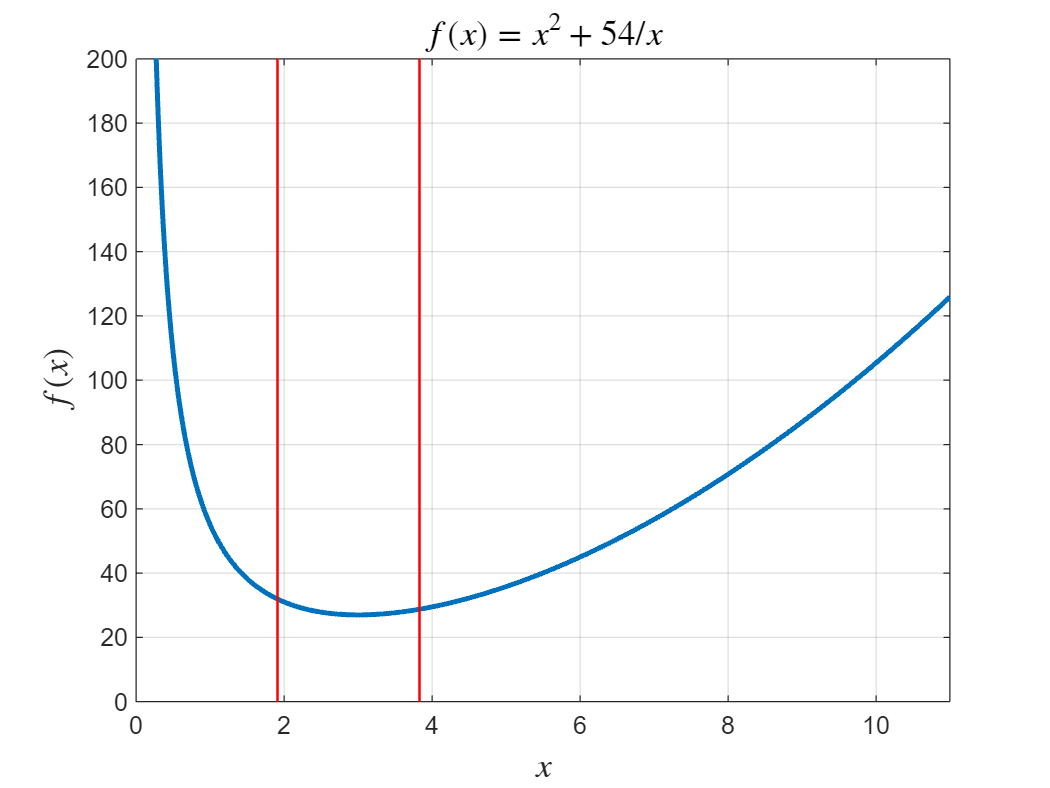

t = 0:0.01:11;
plot(t, f(t), 'LineWidth',2); axis([0, 11, 0, 200]); grid;
title("$f(x) = x^2 + 54/x$", 'Interpreter','latex','FontSize',14);
xlabel("$x$", 'Interpreter','latex','FontSize',14);
ylabel("$f(x)$",'Interpreter','latex','FontSize',14);

hold on
plot([a a], [0, 200], 'LineWidth',1,'Color','red'); 
plot([c c], [0, 200], 'LineWidth',1, 'Color','red');
hold off